## **In the Name of God**

# Wireless Communication

# `CA#2 Part#2`

# **Alireza Javid**

# **810198375**

rng(1)
N = 65536;
L = 200;
Nm = 1e7;
num_carriers = ceil(Nm/N);
bits = bit_gen(Nm,1);
SNRdB = -10:1:50;
Pmax = 1e4;
cp = L-1;

### Part 1: Waterfilling

h = (1 / sqrt(2)) * (randn(1, L) + 1i * randn(1, L));
H=fft(h,N);
[Wk,C]=waterfilling(SNRdB,N,Pmax, H);
N0 = Pmax./((10.^(SNRdB./10))*N);

out_BPSK = BPSK_modulation(bits);
subcarriers = make_subcarriers(out_BPSK', num_carriers, N);
ber_waterfilling = zeros(size(SNRdB));
Y = zeros(length(N0), num_carriers * (N + 2 * cp));
for i = 1: length(N0)
    for j=1:1:num_carriers
        transmited_signal = transmitter(subcarriers(j,:), N, cp, Wk, i);
        rk = channel(transmited_signal, h, N0(i), N, cp);
        Yk = receiver(rk, N, cp);
        Y(i,N*(j-1)+1:N*j) = Yk;
    end
    ber_waterfilling(i) = OFDM_BER(Y(i,1:Nm), bits');
end

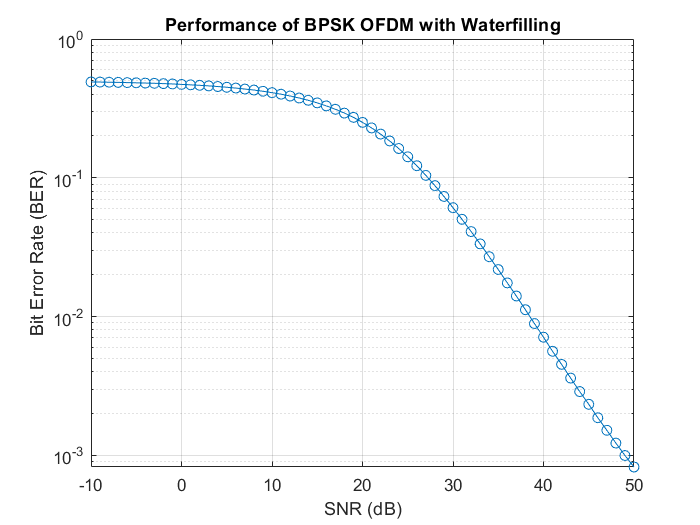

figure;
semilogy(SNRdB,ber_waterfilling,'-o')
grid on
title('Performance of BPSK OFDM with Waterfilling');
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');

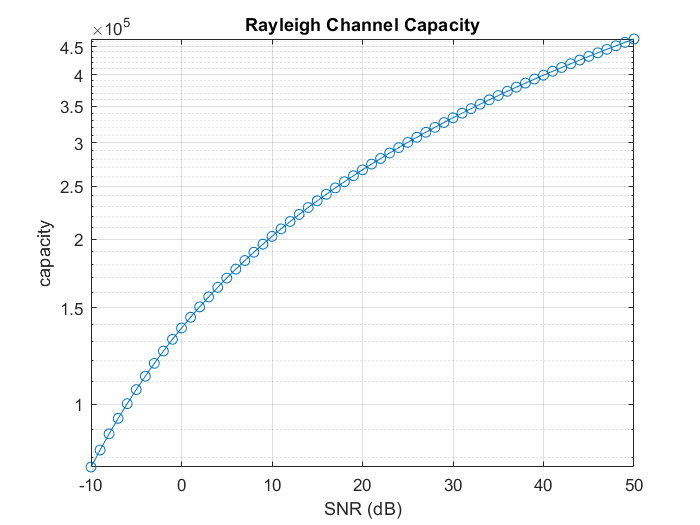

figure;
semilogy(SNRdB,C, '-o')
grid on
xlabel('SNR (dB)');
ylabel('capacity');
title('Rayleigh Channel Capacity');

### Part 2: MRC with M=10

out_BPSK = BPSK_modulation(bits);
subcarriers = make_subcarriers(out_BPSK', num_carriers, N);
ber_MRC = zeros(size(SNRdB));
Y = zeros(length(N0), Nm);
M = 10;
for i = 1: length(N0)
    for k=1:M
        Ym = zeros(1, num_carriers * (N + 2 * cp));
        h = (1 / sqrt(2)) * (randn(1, L) + 1i * randn(1, L));
        H=fft(h,N);
        alpha = conj(H) ./ (abs(H)*sqrt(N0(i)));
        for j=1:1:num_carriers
            transmited_signal = transmitter(subcarriers(j,:), N, cp, 0, i);
            rk = channel(transmited_signal, h, N0(i), N, cp);
            Yk = receiver(rk, N, cp);
            Ym(1,N*(j-1)+1:N*j) = Yk .* alpha;
        end
        Y(i,:) =  Y(i,:) + Ym(1,1:Nm);
    end
    ber_MRC(i) = OFDM_BER(Y(i,:), bits');
end

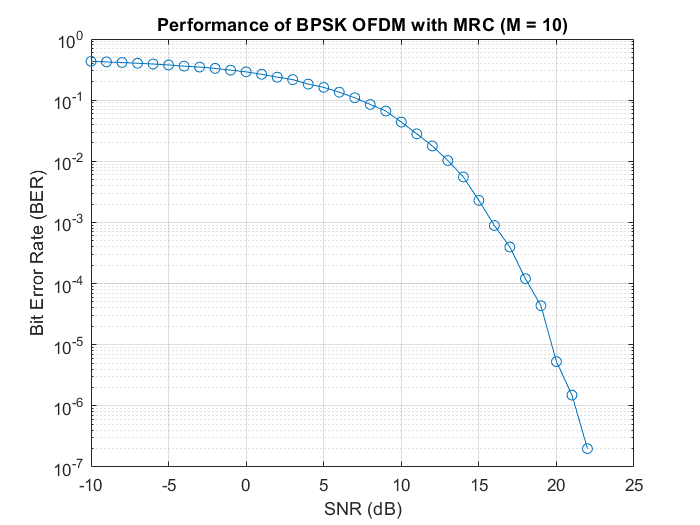

figure;
semilogy(SNRdB,ber_MRC,'-o')
grid on
title('Performance of BPSK OFDM with MRC (M = 10)');
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');

### Part 3: ZF Equalization

h = (1 / sqrt(2)) * (randn(1, L) + 1i * randn(1, L));
H=fft(h,N);
out_BPSK = BPSK_modulation(bits);
subcarriers = make_subcarriers(out_BPSK', num_carriers, N);
ber_ZF = zeros(size(SNRdB));
Y = zeros(length(N0), num_carriers * (N + 2 * cp));
for i = 1: length(N0)
    Wk = 1 ./ H;
    for j=1:1:num_carriers
        transmited_signal = transmitter(subcarriers(j,:), N, cp, 0, i);
        rk = channel(transmited_signal, h, N0(i), N, cp);
        Yk = receiver(rk, N, cp);
        Y(i,N*(j-1)+1:N*j) = Yk .* Wk;
    end
    ber_ZF(i) = OFDM_BER(Y(i,1:Nm), bits');
end

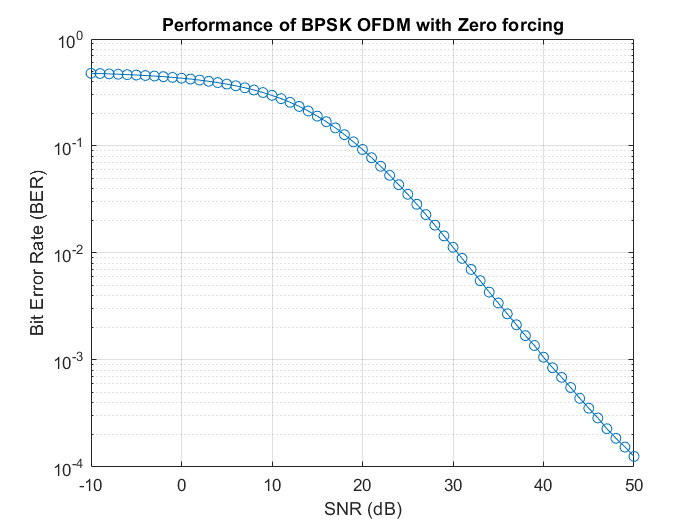

figure;
semilogy(SNRdB,ber_ZF,'-o')
grid on
title('Performance of BPSK OFDM with Zero forcing');
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');

### Part 4: MMSE Equalization

h = (1 / sqrt(2)) * (randn(1, L) + 1i * randn(1, L));
H=fft(h,N);
out_BPSK = BPSK_modulation(bits);
subcarriers = make_subcarriers(out_BPSK', num_carriers, N);
ber_MMSE = zeros(size(SNRdB));
Y = zeros(length(N0), num_carriers * (N + 2 * cp));
for i = 1: length(N0)
    Wk = MMSE(H, N*N0(i));
    for j=1:1:num_carriers
        transmited_signal = transmitter(subcarriers(j,:), N, cp, 0, i);
        rk = channel(transmited_signal, h, N0(i), N, cp);
        Yk = receiver(rk, N, cp);
        Y(i,N*(j-1)+1:N*j) = Yk .* Wk;
    end
    ber_MMSE(i) = OFDM_BER(Y(i,1:Nm), bits');
end

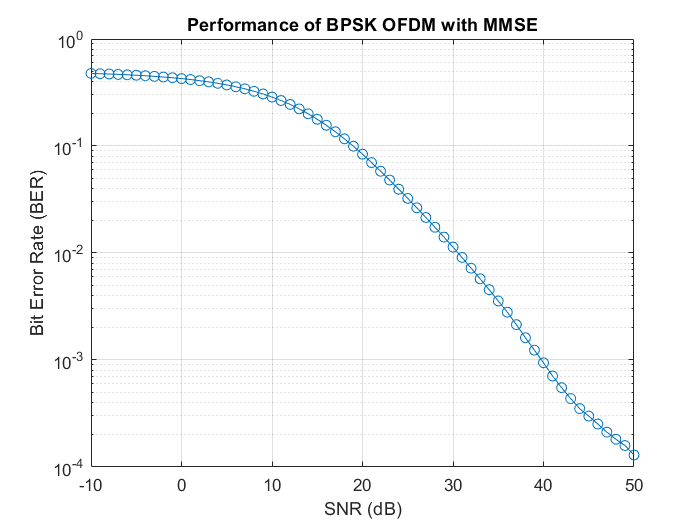

figure;
semilogy(SNRdB,ber_MMSE,'-o')
grid on
title('Performance of BPSK OFDM with MMSE');
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');

### Part 5: MMSE with Clipping

h = (1 / sqrt(2)) * (randn(1, L) + 1i * randn(1, L));
H=fft(h,N);
out_BPSK = BPSK_modulation(bits);
subcarriers = make_subcarriers(out_BPSK', num_carriers, N);
ber_MMSE_clipping = zeros(size(SNRdB));
Y = zeros(length(N0), num_carriers * (N + 2 * cp));
for i = 1: length(N0)
    Wk = MMSE(H, N*N0(i));
    for j=1:1:num_carriers
        transmited_signal = transmitter(subcarriers(j,:), N, cp, 0, i);
        clipped_transmited_signal = clipping(transmited_signal, 0.8);
        rk = channel(clipped_transmited_signal, h, N0(i), N, cp);
        Yk = receiver(rk, N, cp);
        Y(i,N*(j-1)+1:N*j) = Yk .* Wk;
    end
    ber_MMSE_clipping(i) = OFDM_BER(Y(i,1:Nm), bits');
end

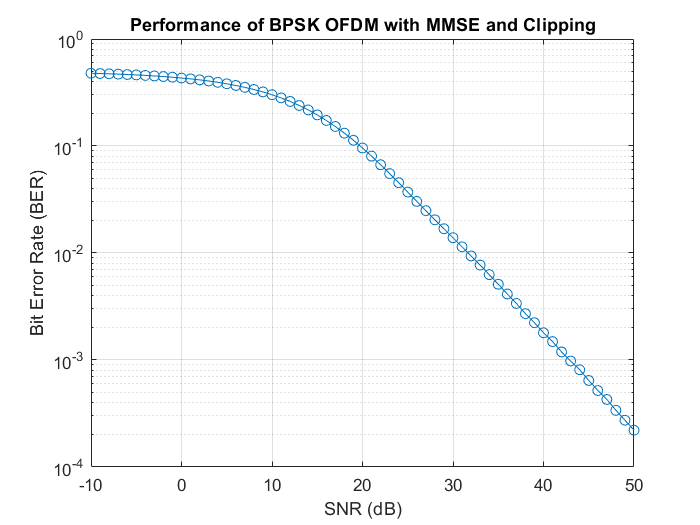

figure;
semilogy(SNRdB,ber_MMSE_clipping,'-o')
grid on
title('Performance of BPSK OFDM with MMSE and Clipping');
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');

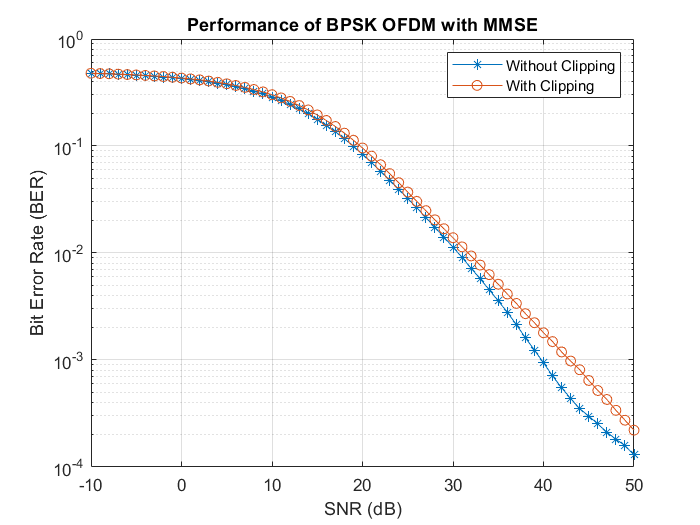

figure;
semilogy(SNRdB,ber_MMSE,'-*',SNRdB,ber_MMSE_clipping,'-o')
grid on
title('Performance of BPSK OFDM with MMSE');
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
legend({'Without Clipping','With Clipping'})

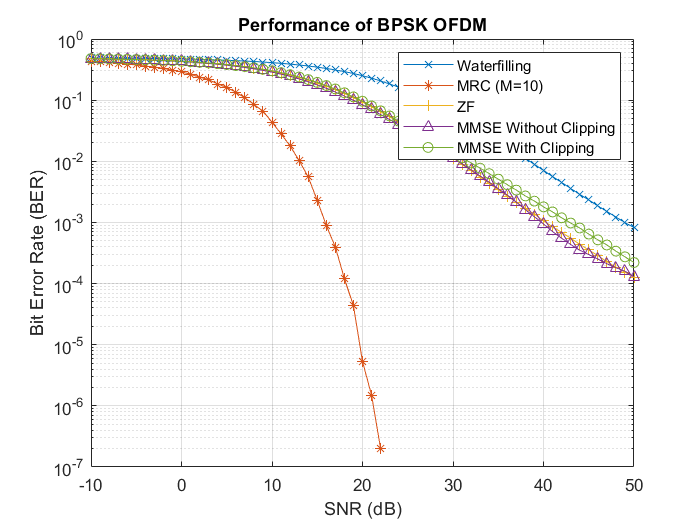

figure;
semilogy(SNRdB,ber_waterfilling,'-x',SNRdB,ber_MRC,'-*', ...
    SNRdB,ber_ZF,'-+', SNRdB,ber_MMSE,'-^', SNRdB,ber_MMSE_clipping,'-o')
grid on
title('Performance of BPSK OFDM');
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
legend({'Waterfilling','MRC (M=10)', 'ZF', ...
    'MMSE Without Clipping', 'MMSE With Clipping'})

function b = bit_gen(N, k)
    b = randi([0 1], N, k);
    b = double(b);
end
function x = BPSK_modulation(b)
    x = 2*b - 1;
end

function b = BPSK_demodulation(x)
    b = real(x) > 0; 
end

function output = make_subcarriers(input, nc, N)
    input = [input, zeros(1, N - mod(length(input), N))];
    output = reshape(input, N, nc).';
end

function symbol_cp = add_CP(symbol, cp_len, N)
    cp = symbol(:,N-cp_len+1:end);
    symbol_cp = [cp, symbol];
end

function symbol = remove_CP(symbol_cp, cp_len, N)
    symbol = symbol_cp(:,cp_len + 1:cp_len + N);
end

function [Wk, C] = waterfilling(SNR_db, nc, Pmax, H)
% SNR = Pmax / n_c*N_0 
    N0 = Pmax ./ (10 .^ (SNR_db ./ 10)) ./ nc;
    Wk = zeros(length(SNR_db), nc);
    Pi = zeros(length(SNR_db), nc);
    C = zeros(length(SNR_db), 1);
    
    for p = 1:length(N0)
        upper = min(N0(p) ./ abs(H).^2);
        lower = 1e4;
        x0 = [1/lower, 1/upper];
        
        func = @(lambda) Pmax - sum(max((1 ./ lambda) - ...
            (N0(p) ./ abs(H).^2), 0));
        roots(p) = fzero(func, x0);
        
        Pi(p, :) = max((1 ./ roots(p)) - (N0(p) ./ abs(H).^2), 0);
        C(p) = sum(log10(1 + (Pi(p, :) .* abs(H).^2) ./ N0(p)));
        Wk(p, :) = sqrt(Pi(p, :)) .* exp(-1i * angle(H));
    end
end
function transmited_signal = transmitter(x, N, cp, Wk, i)
    if Wk == 0
        subcarrier = x;
    else
        subcarrier = x .* Wk(i,:);
    end
    time_domain_signal = ifft(subcarrier, N);
    transmited_signal = add_CP(time_domain_signal, cp, N);
end
function received_signal = channel(transmited_signal, h, N0, N, cp)
    w =  sqrt(N0/2) * (randn(N+2*cp, 1) + ...
                1i*randn(N+2*cp, 1));
    received_signal = conv(transmited_signal,h) + w';
end
function freq_domain_signal = receiver(received_signal, N, cp)
    received_signal = remove_CP(received_signal, cp, N);
    freq_domain_signal = fft(received_signal);
end

function ber = OFDM_BER(Y, bits)
    det_bits = BPSK_demodulation(Y);
    numErrors = sum(det_bits ~= bits);
    ber = numErrors / length(bits);
end

function Wk =MMSE(H,N0)
    Wk = conj(H) ./ (abs(H).^2 + N0);
end

function clipped_signal = clipping(X, alpha)
    Mk = max(abs(X));
    threshold = alpha * Mk;
    clipped_signal = X;
    clipped_signal(abs(clipped_signal) > threshold) = threshold * exp(1j ...
        * angle(clipped_signal(abs(clipped_signal) > threshold)));
end